a=1+mod(112,3);
t=[-1:0.001:1];
y1=sin(20*pi*a*t)

y1 =     0.0000    0.1253    0.2487    0.3681    0.4818    0.5878    0.6845    0.7705    0.8443    0.9048    0.9511    0.9823    0.9980    0.9980    0.9823    0.9511    0.9048    0.8443    0.7705    0.6845    0.5878    0.4818    0.3681    0.2487    0.1253   -0.0000   -0.1253   -0.2487   -0.3681   -0.4818   -0.5878   -0.6845   -0.7705   -0.8443   -0.9048   -0.9511   -0.9823   -0.9980   -0.9980   -0.9823   -0.9511   -0.9048   -0.8443   -0.7705   -0.6845   -0.5878   -0.4818   -0.3681   -0.2487   -0.1253


subplot(2,2,1)
plot(t,y1)
y2=cos(5*pi*a*t+(pi/4))

y2 =     0.7071    0.6845    0.6613    0.6374    0.6129    0.5878    0.5621    0.5358    0.5090    0.4818    0.4540    0.4258    0.3971    0.3681    0.3387    0.3090    0.2790    0.2487    0.2181    0.1874    0.1564    0.1253    0.0941    0.0628    0.0314   -0.0000   -0.0314   -0.0628   -0.0941   -0.1253   -0.1564   -0.1874   -0.2181   -0.2487   -0.2790   -0.3090   -0.3387   -0.3681   -0.3971   -0.4258   -0.4540   -0.4818   -0.5090   -0.5358   -0.5621   -0.5878   -0.6129   -0.6374   -0.6613   -0.6845


subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t)

y3 =    54.5982   54.3802   54.1631   53.9469   53.7315   53.5170   53.3034   53.0906   52.8787   52.6676   52.4573   52.2479   52.0393   51.8316   51.6247   51.4186   51.2133   51.0089   50.8053   50.6025   50.4004   50.1992   49.9988   49.7993   49.6005   49.4024   49.2052   49.0088   48.8132   48.6183   48.4242   48.2309   48.0384   47.8466   47.6556   47.4654   47.2759   47.0871   46.8992   46.7119   46.5255   46.3397   46.1548   45.9705   45.7870   45.6042   45.4222   45.2408   45.0602   44.8803


subplot(2,2,3)
plot(t,y3)
y4=(exp(-0.25*a*t)).*(sin(20*pi*t))

y4 =     0.0000    0.1035    0.2064    0.3085    0.4092    0.5082    0.6051    0.6995    0.7911    0.8795    0.9643    1.0452    1.1219    1.1941    1.2615    1.3239    1.3810    1.4326    1.4784    1.5184    1.5524    1.5802    1.6018    1.6170    1.6258    1.6282    1.6242    1.6138    1.5970    1.5739    1.5447    1.5094    1.4681    1.4211    1.3686    1.3107    1.2477    1.1798    1.1074    1.0306    0.9499    0.8655    0.7778    0.6871    0.5937    0.4981    0.4007    0.3018    0.2017    0.1010


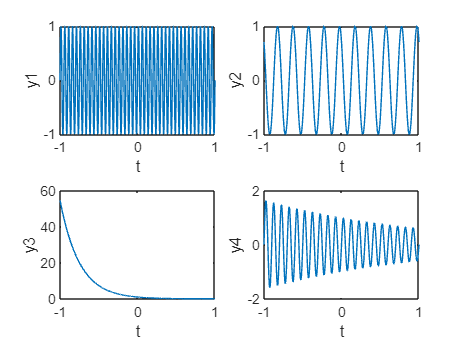

subplot(2,2,4)
plot(t,y4)

subplot(2,2,1)
xlabel("t")
ylabel("y1")

subplot(2,2,2)
xlabel("t")
ylabel("y2")
subplot(2,2,3)
xlabel("t")
ylabel("y3")
subplot(2,2,4)
xlabel("t")
ylabel("y4")

a=1+mod(112,3);
t=[-5:0.001:5];
x=inline('exp(-2*t)','t')

x =

     Inline function:
     x(t) = exp(-2*t)



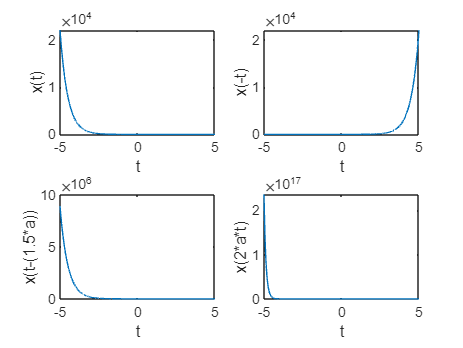

subplot(2,2,1)
plot(t,x(t))
subplot(2,2,2)
plot(t,x(-t))
subplot(2,2,3)
plot(t,x(t-(1.5*a)))
subplot(2,2,4)
plot(t,x(2*a*t))

subplot(2,2,1)
xlabel("t")
ylabel("x(t)")
subplot(2,2,2)
xlabel("t")
ylabel("x(-t)")
subplot(2,2,3)
xlabel("t")
ylabel("x(t-(1.5*a))")
subplot(2,2,4)
xlabel("t")
ylabel("x(2*a*t)")

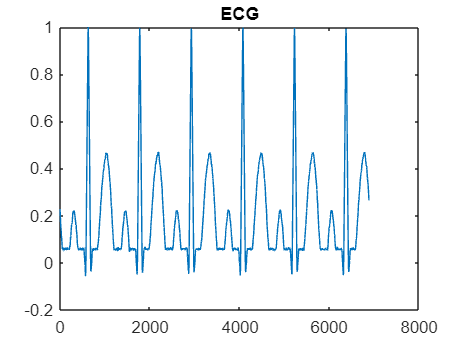

ECG = load("ECG_Data.txt");
subplot(1,1,1)
plot(ECG)

title("ECG")

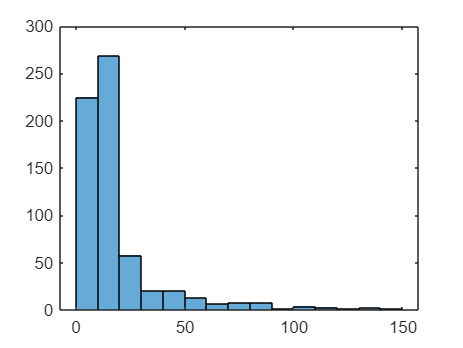

eg=readmatrix('RainFallIndia_Jan.txt');

plot(eg)
histogram(eg)

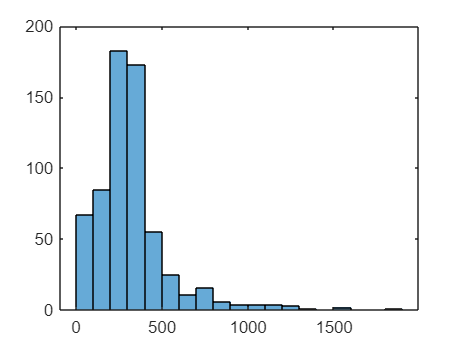

ex=readmatrix('RainFallIndia_July.txt');
plot(ex)
histogram(ex)

[y,Fs]=audioread('Track002.wav')
sound(y,Fs)

[y,Fs]=audioread('Track002.wav')
sound(y,Fs)
t=[0:0.001:5];
a=sin(200*t);
b=sin(220*t);
c=[a,b];

filename='convaluted_signal.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal.wav");
sound(y,Fs)

%Q5
notes=["Do" "Re" "Mi" "Fa" "So" "La" "Ti" "Do"];
freq=[261.6 293.6 329.6 349.2 392.0 440.0 493.8 523.25];

a=[];
for n=1:8
   t=0:0.000125:1; % Note duration
  a=[a sin(2*pi*freq(n)*t)]; % Signal
end
sound(a);

% Saving as .wav file
Fs=44100;
filename="DoReMi.wav";
audiowrite(filename,a,Fs);

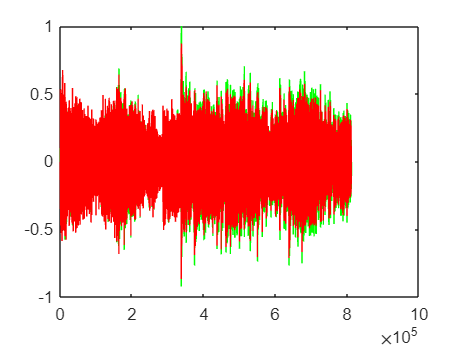

a=audioread('Track002.wav');
b=load('ConvFile1.txt');
c=conv(a,b);
max_amplitude=max(max(c),abs(min(c)));
c=c/max_amplitude;
filename='convaluted_signal1.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal1.wav");
sound(y,Fs)
t=0:length(a)-1;
%subplot(2,1,1)
%plot(t,a)
t1=0:length(c)-1;
%subplot(2,1,2)
plot(t1,c,'g',t,a,'r')

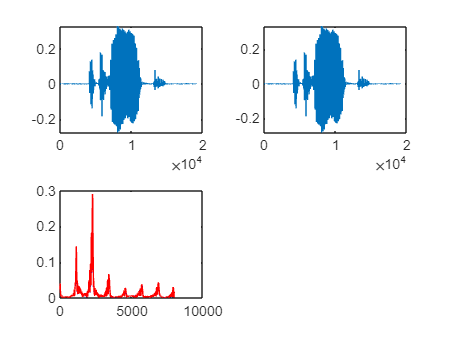

a=1+mod(112,3);
f=250*a;
data=importdata("speech.wav");
[s,Fs]=audioread("speech.wav");
y1=fn(s,f,Fs);
t=1/Fs; L=1500; t=(0:L-1)*t;
y0=fft(y1);
s0=fft(s);
f=Fs*(0:(L/2))/L;
P2=abs(y0/L);
P1=P2(1:L/2+1);
P1(2:end-1)=2*P1(2:end-1);
Q2=abs(s0/L);
Q1=Q2(1:L/2+1);
Q1(2:end-1)=2*Q1(2:end-1);
subplot(2,2,1);
plot(y1);
subplot(2,2,2);
plot(s);
subplot(2,2,3);
plot(f,P1,'blue',f,Q1,'red');


sound(y,Fs)


function y=fn(s,F,Fs)
y=s.*cos(2.*pi.*F./Fs);
end

